# Framework to combine multiple stiffnesses and calculate the total stiffness under any angle

An explanation of these calculations can be found in the Mikroniek (vol. 63, Issue 3) in the article *"Series, Parallel or something else"*

Author: Kevin Looman

Version 1, 2023

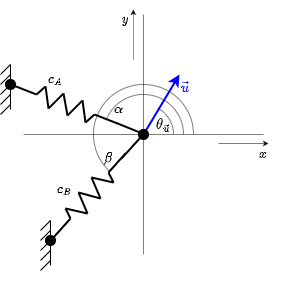

clear all

%Input:
Phi(1) = deg2rad(180);        %Angle of the stiffnesses [rad] w.r.t. the x-axis
Phi(2) = deg2rad(235);
%Phi(3) = deg2rad(230);

c(1) = 1000;                  %Value of the stiffnesses [N/m]
c(2) = 10;
%c(3) = 50;

if length(Phi) ~= length(c) 
    error("Number of stiffness angles and stiffness values do not match");
end

%Definition of some usefull variables:
N = length(Phi);
th = deg2rad(linspace(0,360,361));  %angle of the force OR displacement vector

## Plot input system

In order to check your input, the system is plotted

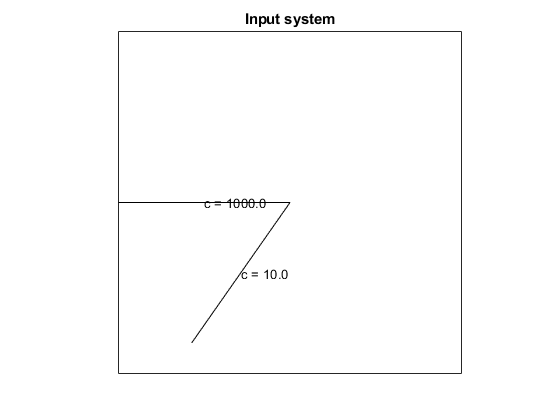

figure
for i = 1:N
    plot([0 cos(Phi(i))], [0, sin(Phi(i))],'k-')
    text(0.5*cos(Phi(i)),0.5*sin(Phi(i)),sprintf('c = %.1f',c(i)))
    hold on
end
axis equal
xlim([-1,1])
ylim([-1,1])
set(gca,'XTick',[])
set(gca,'YTick',[])
title("Input system")

## Calculating the stiffness tensor $C$ as shown in paper

As discussed, the virtual displacement method is used to derive a stiffness matrix C. First the contribution to the reaction force of each spring is found and added up to form the matrix C

Step 1:

Step 2:

Step 3:

for i = 1:N
    F(:,:,i) = c(i).*[(cos(Phi(i)))^2         , cos(Phi(i))*sin(Phi(i));
                  cos(Phi(i))*sin(Phi(i)) , (sin(Phi(i)))^2]; %the times \vec(u) part is left out
end
C = sum(F,3);

## Calculating total stiffness of the system

Imposed displacement:

Imposed force:

C_inv = inv(C);
for i = 1:length(th)
    c_ID(i) = [cos(th(i)), sin(th(i))]*C*[cos(th(i)); sin(th(i))];  % Imposed displacement
    c_IF(i) = 1/([cos(th(i)), sin(th(i))]*C_inv*[cos(th(i)); sin(th(i))]); % Imposed force
end

## Plotting results

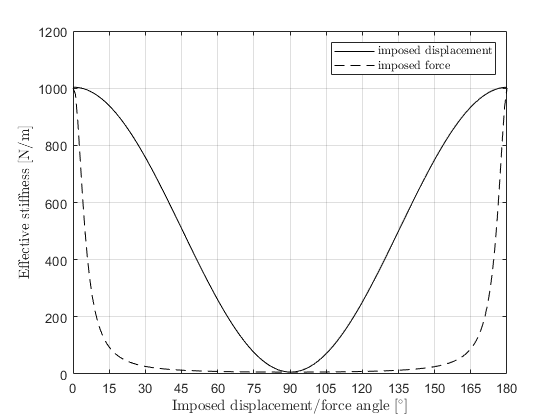

figure
plot(rad2deg(th),c_ID,'k-')
hold on
plot(rad2deg(th),c_IF,'k--')
legend('imposed displacement','imposed force','interpreter','latex')
grid on
xlim([0,180])
xticks(0:15:180)
xlabel('Imposed displacement/force angle [$$ ^{\circ} $$]','interpreter','latex')
ylabel('Effective stiffness [N/m]','interpreter','latex')

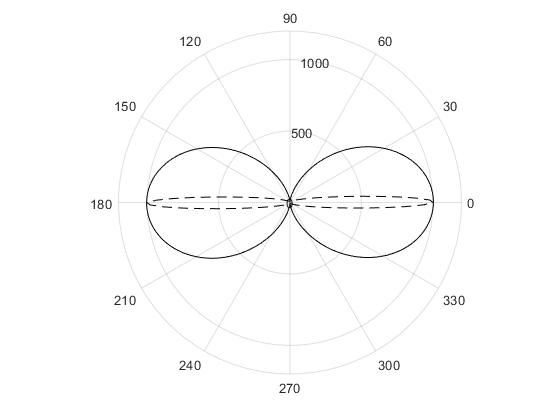


figure
polarplot(th,c_ID,'k-')
%pax = gca
hold on
polarplot(th,c_IF,'k--')